# Análisis de la red de movilidad

GPLv3 Miguel Rebollo @mrebollo. Abril 2020

clear all
encoding = slCharacterEncoding('UTF-8');

% mobiity data
flujosorigen = importflujo('../data/flujos_origen.csv');
zonasINE = importzonas('../data/zonas_ine.csv');
load flujos.mat

coor = zeros(numel(labels),2);
for i=1:length(coor)
    idx = strcmp(labels(i),[zonasINE{:,1}]);
    coor(i,:) = [zonasINE{idx,3} zonasINE{idx,4}];
end

% shape of CV
spainCS = shaperead("../data/ComunidadesAutonomas_ETRS89_30N/Comunidades_Autonomas_ETRS89_30N.shp");
idx = strcmp({spainCS.Texto},'Comunidad Valenciana');
comval = spainCS(idx);

for i=1:length(comval)
    [y, x] = utm2ll(comval(i).BoundingBox(:,1), comval(i).BoundingBox(:,2), 30);
    comval(i).BoundingBox = [x y];    
    [comval(i).Y, comval(i).X] = utm2ll(comval(i).X, comval(i).Y, 30);
end


% network creation
G = digraph(flujos);

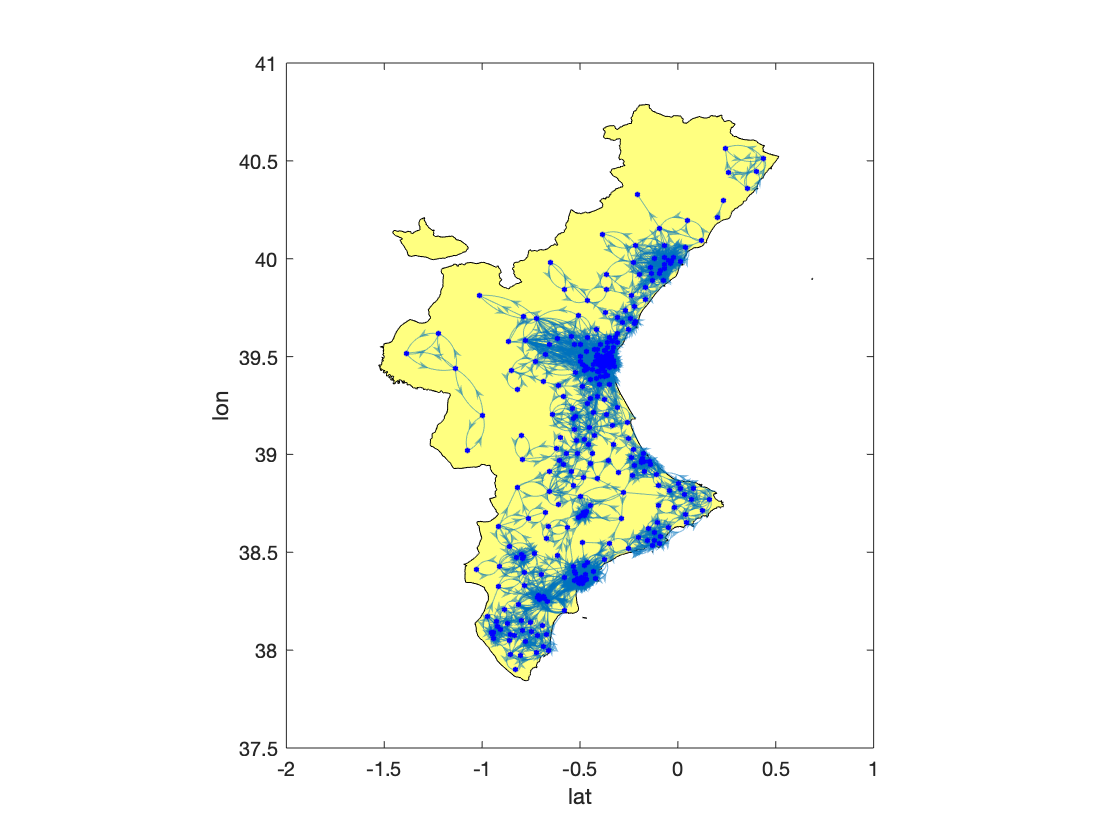

% plot network on contour
figure
mapshow(comval)
hold on
plot(G,'XData',coor(:,1),'YData',coor(:,2),'NodeColor','b')
hold off
xlabel('lat')
ylabel('lon')
box

ax = axis;

% plot network on map
street = 'http://www.ign.es/wms-inspire/ign-base?SERVICE=WMS&REQUEST=GetCapabilities&VERSION=1.3.0';
photo = 'https://www.ign.es/wms-inspire/pnoa-ma?SERVICE=WMS&REQUEST=GetCapabilities&VERSION=1.3.0';

lonlim = [-2 1 ];
latlim = [37.5 41];
wms = wmsinfo(street);
[map, raster] = wmsread(wms.Layer(3),'latlim',latlim,'lonlim',lonlim);


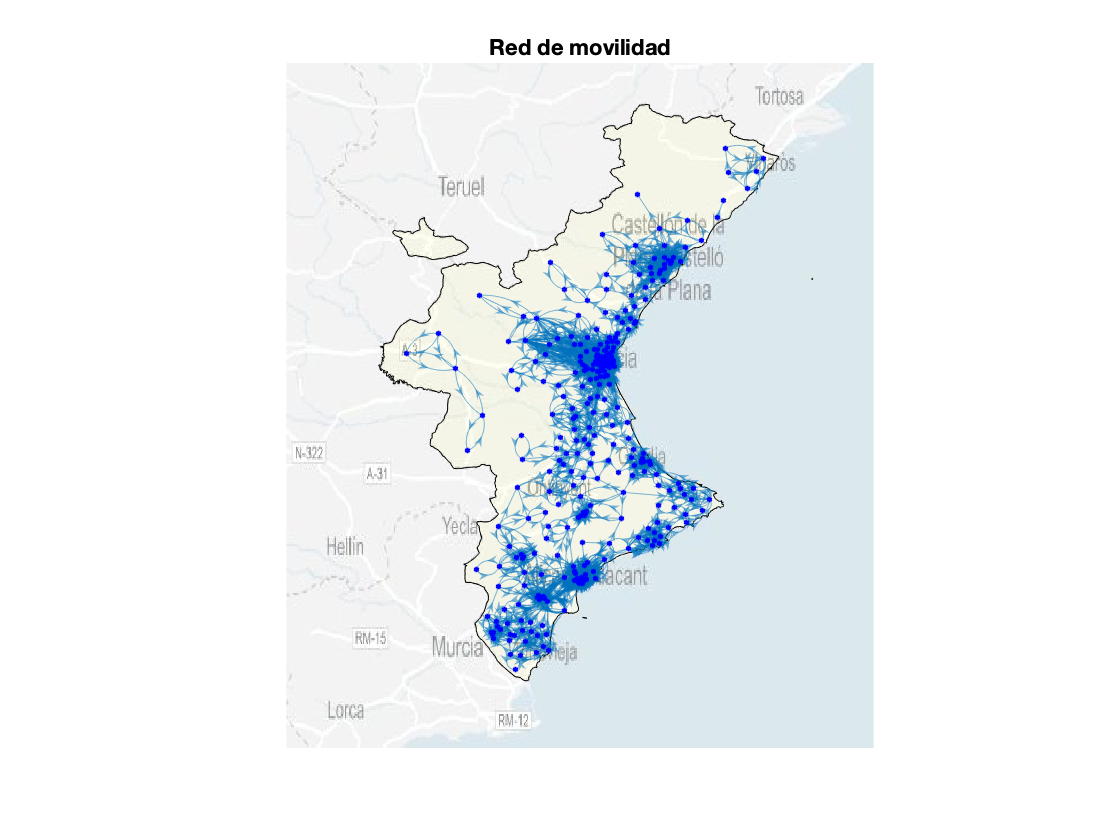

figure;
geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
plot(G,'XData',coor(:,1),'YData',coor(:,2),'NodeColor','b')
hold off
axis image off
title('Red de movilidad')

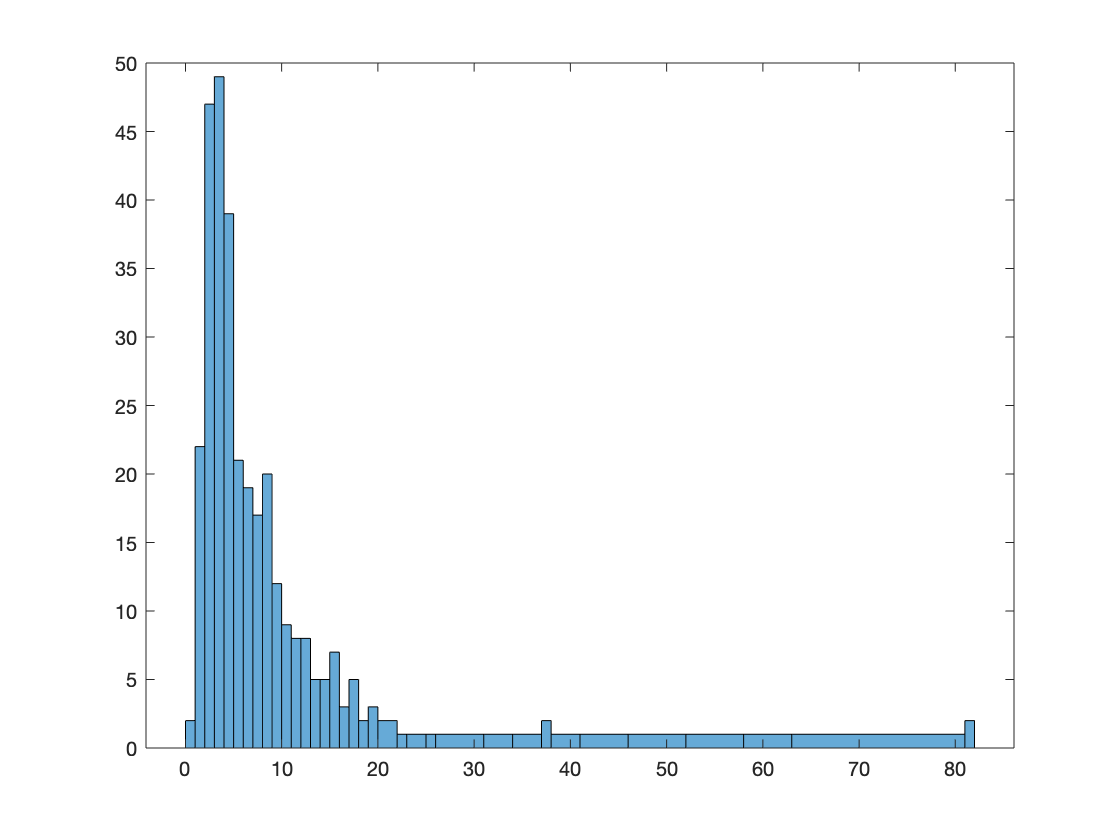

% degree
G.Nodes.XCoord = coor(:,1);
G.Nodes.YCoord = coor(:,2);

indeg = indegree(G);
figure
hin = histogram(indeg,unique(indeg));

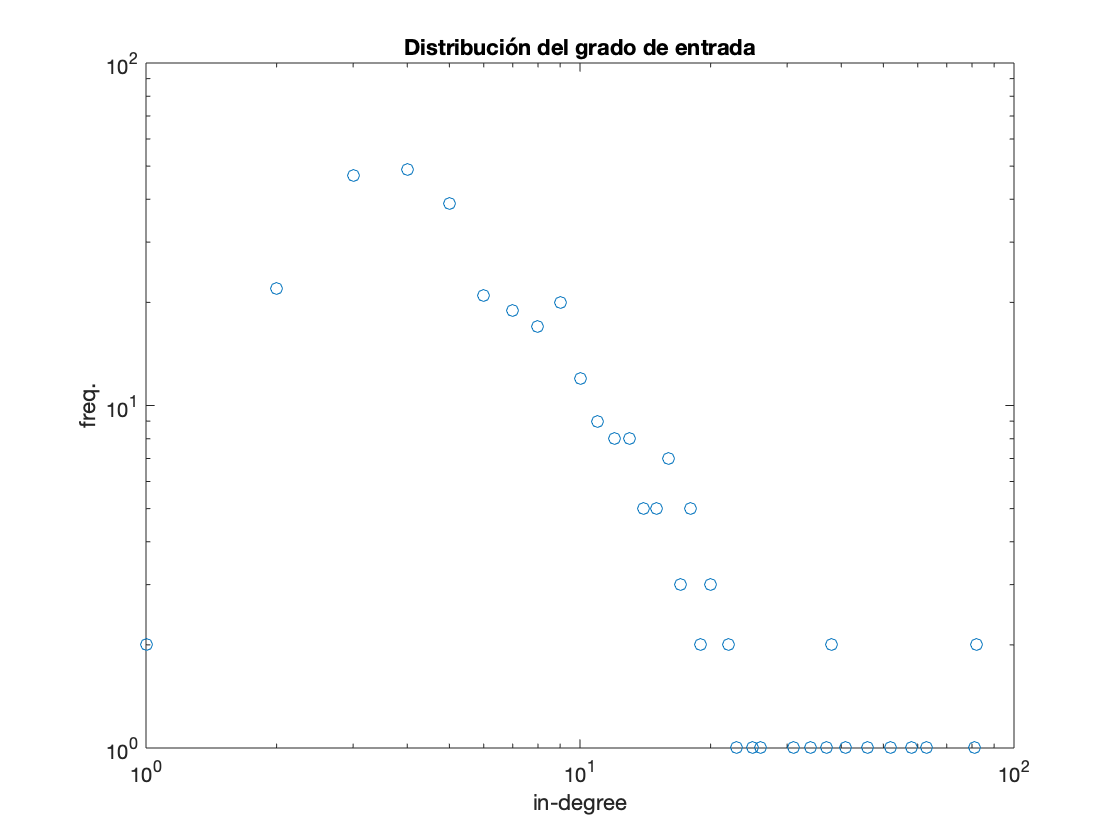

loglog(hin.BinEdges(2:end),hin.Values,'o');
title('Distribución del grado de entrada')
xlabel('in-degree');
ylabel('freq.')

mean(indeg)

ans = 7.7913

std(indeg)

ans = 10.1518

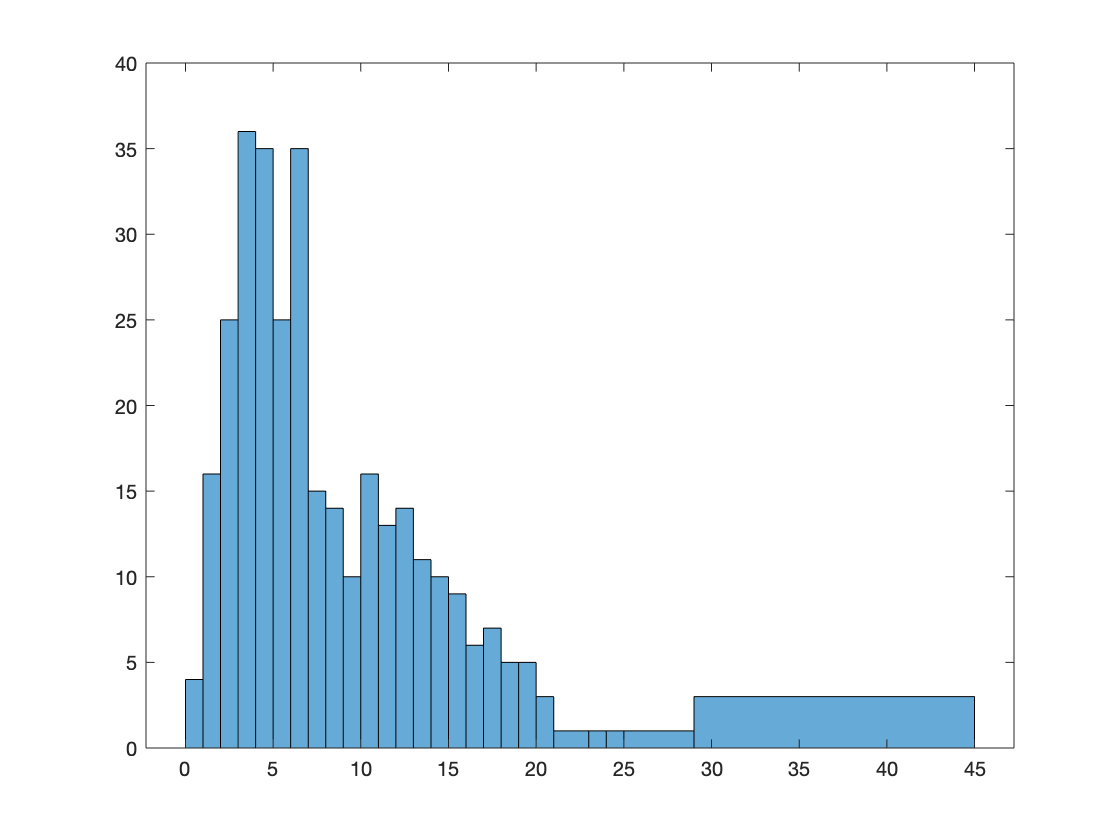


outdeg = outdegree(G);
figure
hout = histogram(outdeg,unique(outdeg));

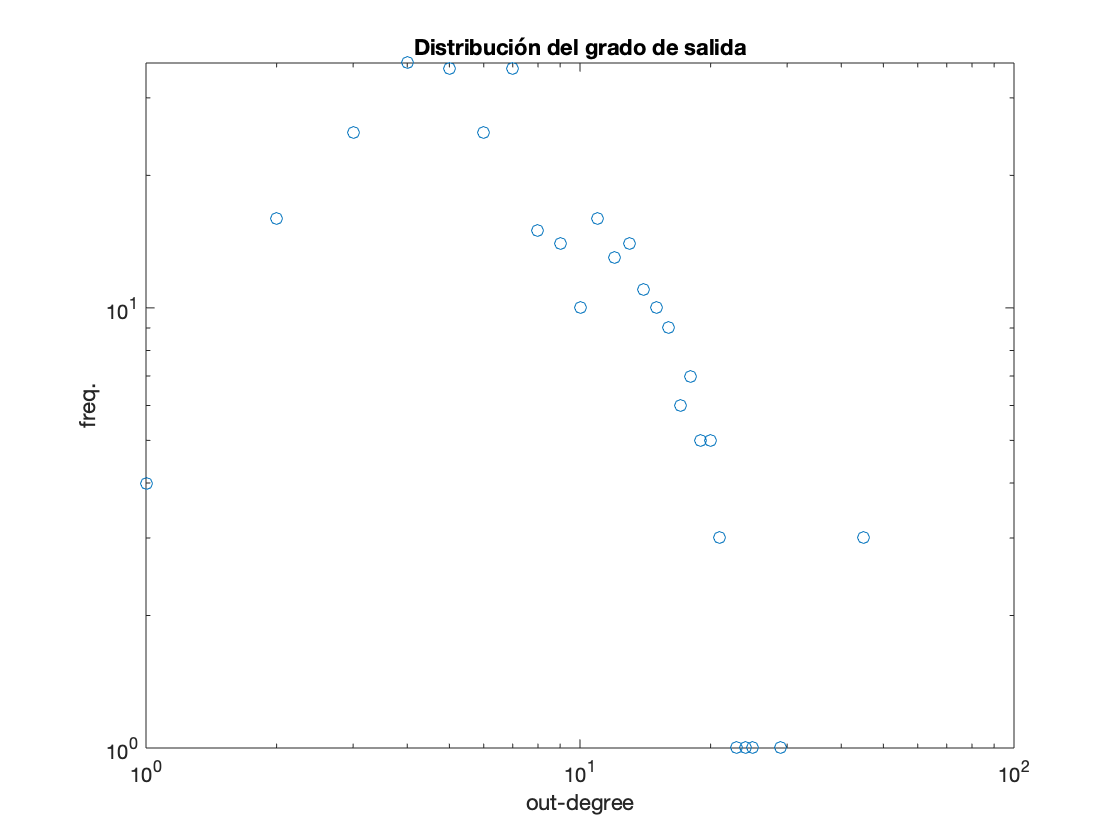

loglog(hout.BinEdges(2:end),hout.Values,'o');
title('Distribución del grado de salida')
xlabel('out-degree');
ylabel('freq.')

mean(outdeg)

ans = 7.7913

std(outdeg)

ans = 5.8457


dist = distances(G,'Method','unweighted');
diam = max(dist(isfinite(dist)))

diam = 28

avg_short_path = mean(dist(isfinite(dist)))

avg_short_path = 8.9531

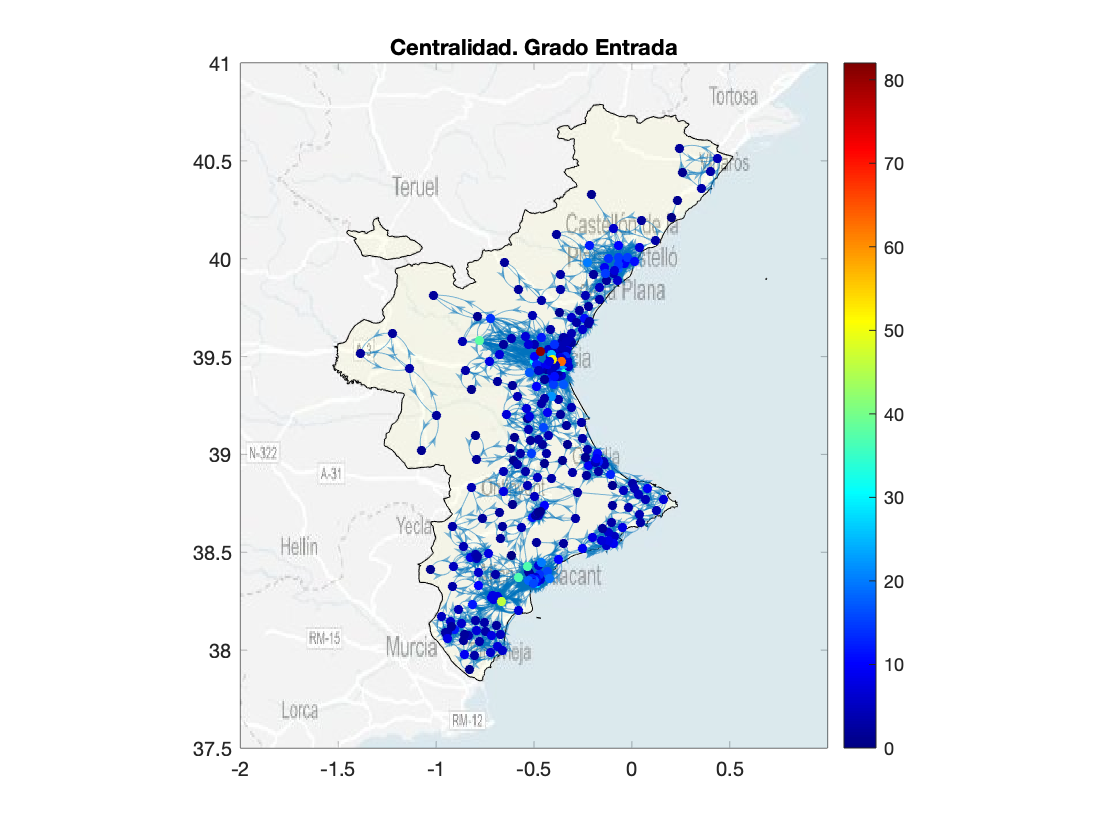

figure
geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
p0 = plot(G,'XData',coor(:,1),'YData',coor(:,2),'MarkerSize',4);
hold off
udc = centrality(G,'indegree');
p0.NodeCData = udc;
colormap jet
caxis([0 max(udc)])
colorbar
title('Centralidad. Grado Entrada')
axis image 
box

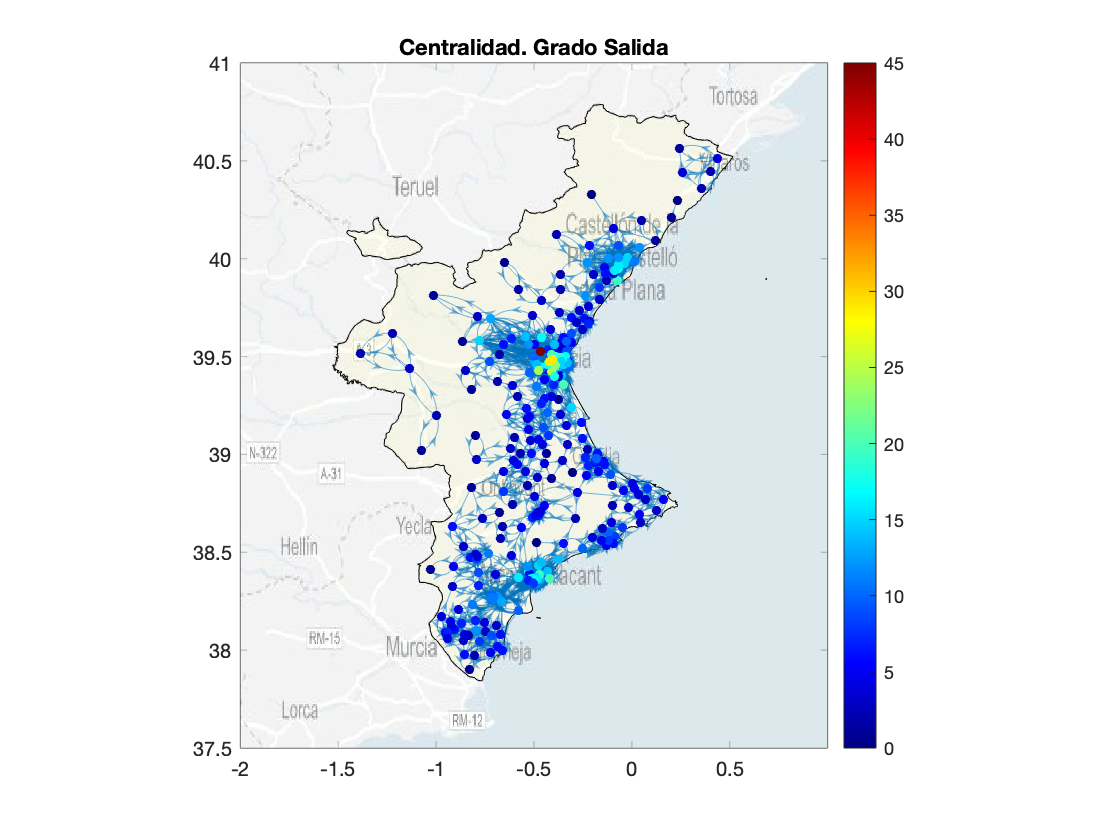


figure
geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
p0 = plot(G,'XData',coor(:,1),'YData',coor(:,2),'MarkerSize',4);
hold off
udc = centrality(G,'outdegree');
p0.NodeCData = udc;
colormap jet
caxis([0 max(udc)])
colorbar
title('Centralidad. Grado Salida')
axis image 
box

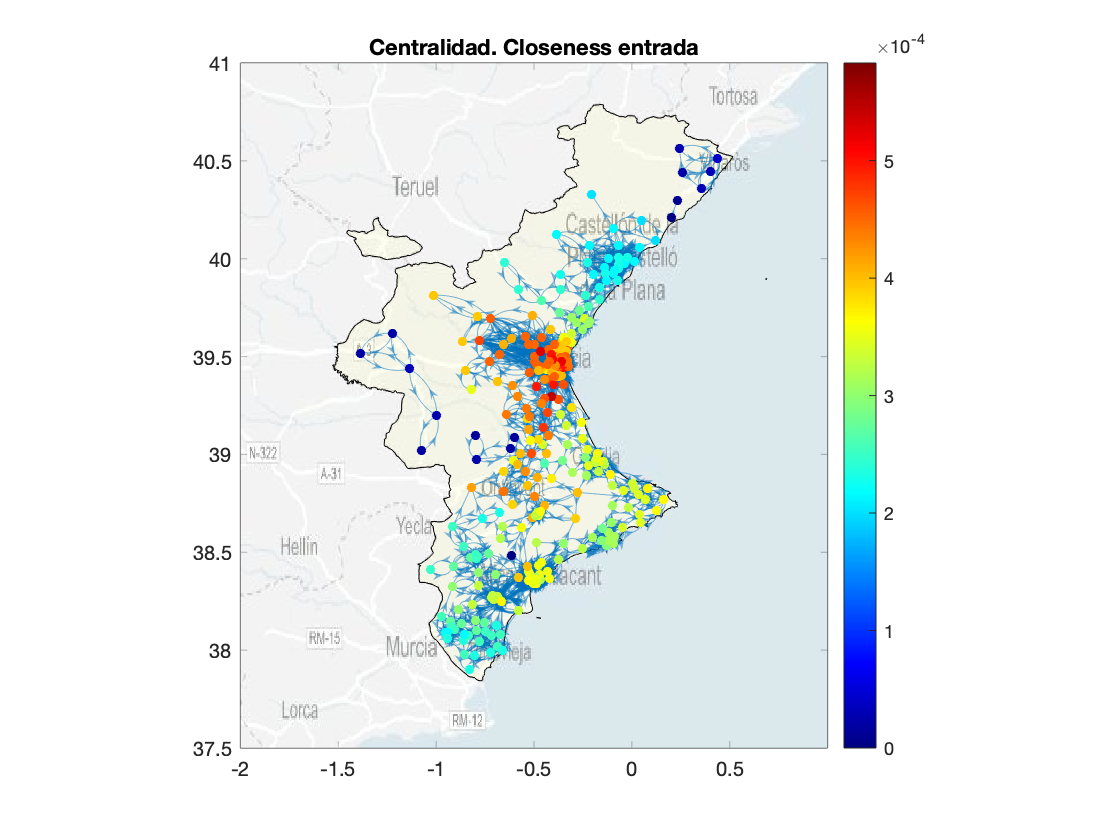

geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
p1 = plot(G,'XData',coor(:,1),'YData',coor(:,2),'MarkerSize',4);
hold off
ucc = centrality(G,'incloseness');
p1.NodeCData = ucc;
colormap jet
caxis([0 max(ucc)])
colorbar
title('Centralidad. Closeness entrada')
axis image 
box

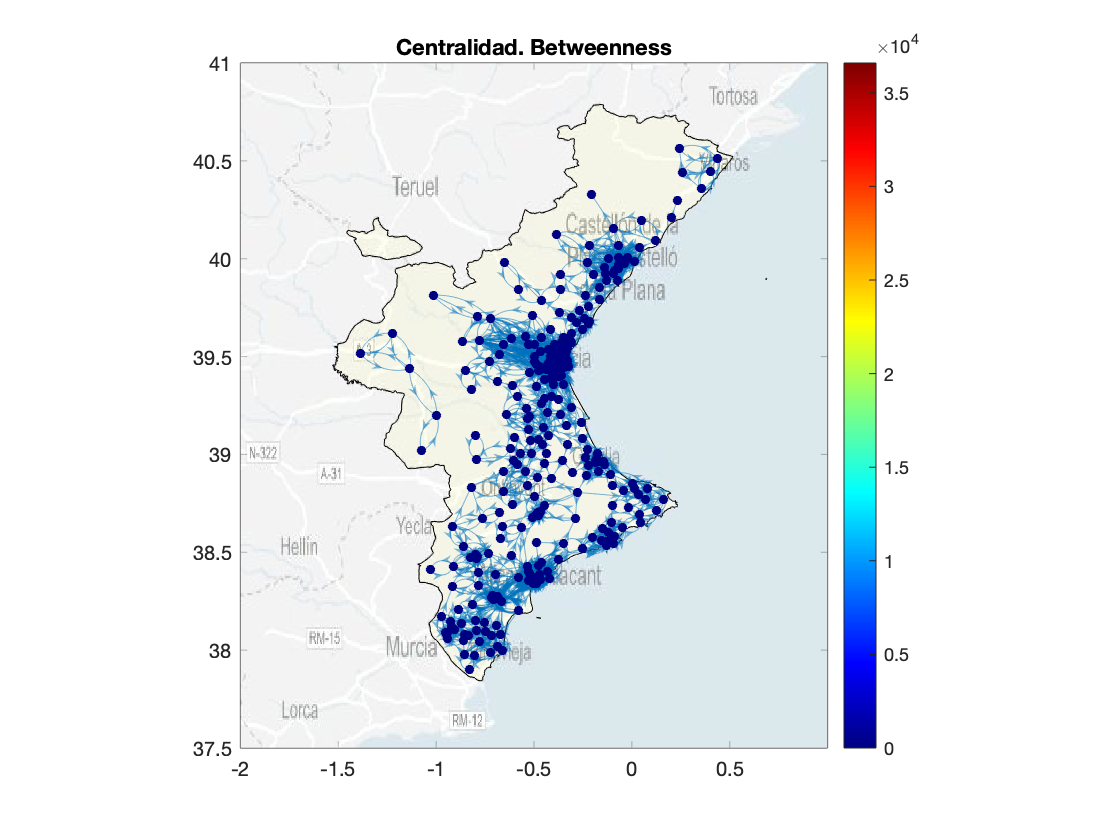

geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
p2 = plot(G,'XData',coor(:,1),'YData',coor(:,2),'MarkerSize',4);
hold off
wbc = centrality(G,'betweenness');
n = numnodes(G);
p2.NodeCData = 2*wbc./((n-2)*(n-1));
colormap jet
caxis([0 max(wbc)])
colorbar
title('Centralidad. Betweenness')
axis image 
box

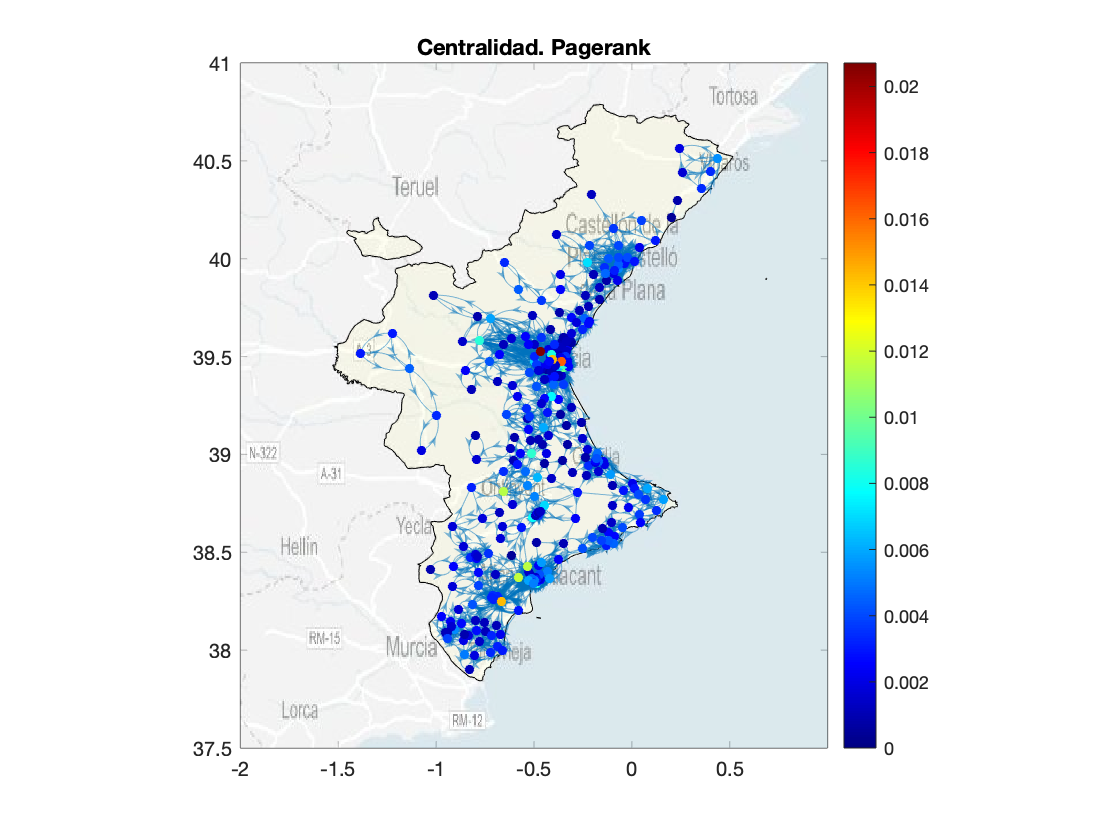

geoshow(map,raster,'FaceAlpha', 0.7)
hold on
mapshow(comval, 'FaceAlpha', 0.1);
p3 = plot(G,'XData',coor(:,1),'YData',coor(:,2),'MarkerSize',4);
hold off
prc = centrality(G,'pagerank');
p3.NodeCData = prc;
colormap jet
caxis([0 max(prc)])
colorbar
title('Centralidad. Pagerank')
axis image 
box

aux = flujos;
n = size( flujos,2 );
eff = zeros(n,1);
del = randperm(n);
connectedComponent = ones(n,1);

E = efficiency(flujos)

E = 0.1662


for id = 1:n
    flujos(:,del(id) ) = 0;
    flujos(del(id),:) = 0;
    eff(id) = efficiency(flujos) / E;
    [~,binsizes] = conncomp(rmnode(G,del(1:id)));
    connectedComponent(id) = numel(binsizes);
end
flujos = aux;

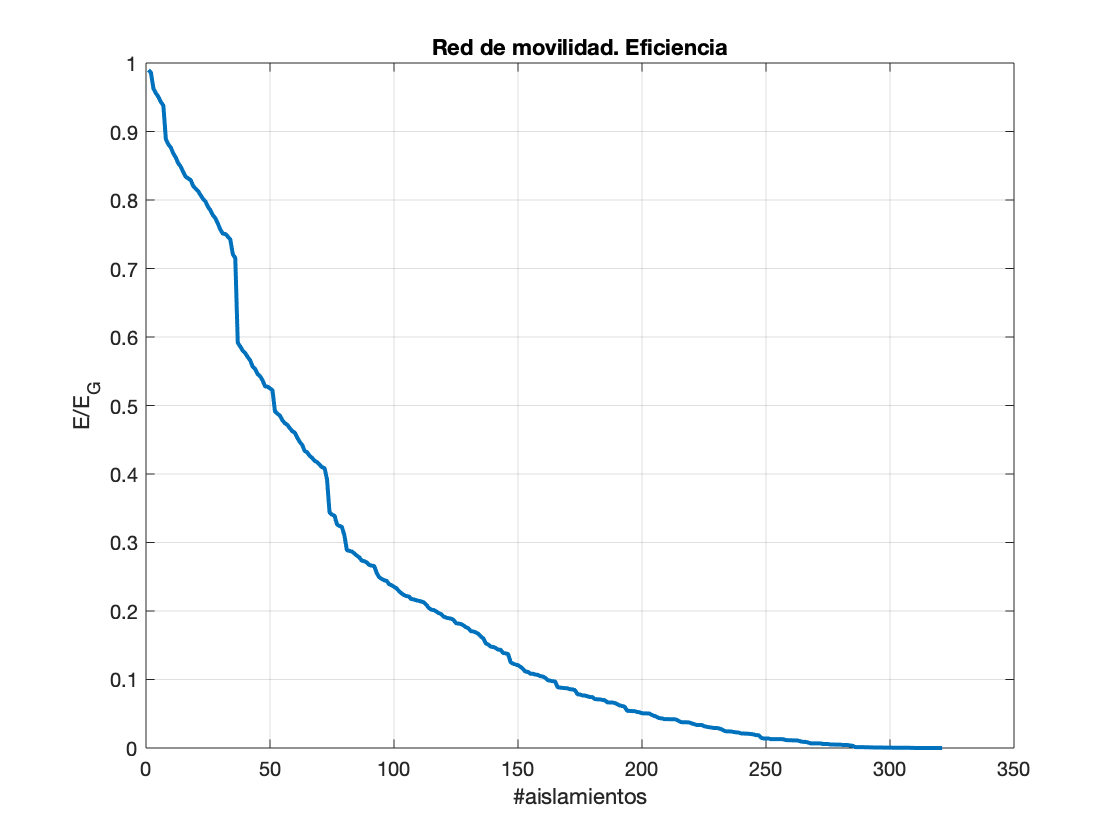

figure;
plot(eff, 'Linewidth', 2);
grid
title 'Red de movilidad. Eficiencia'
xlabel('#aislamientos')
ylabel('E/E_G')

aux = flujos;
n = size( flujos,2 );
effbtw = zeros(n,1);
[~,del] = sort(wbc,'descend');
connectedComponentBtw = ones(n,1);

E = efficiency(flujos)

E = 0.1662


for id = 1:n
    flujos(:,del(id) ) = 0;
    flujos(del(id),:) = 0;
    effbtw(id) = efficiency(flujos) / E;
    [~,binsizes] = conncomp(rmnode(G,del(1:id)));
    connectedComponentBtw(id) = numel(binsizes);
end
flujos = aux;

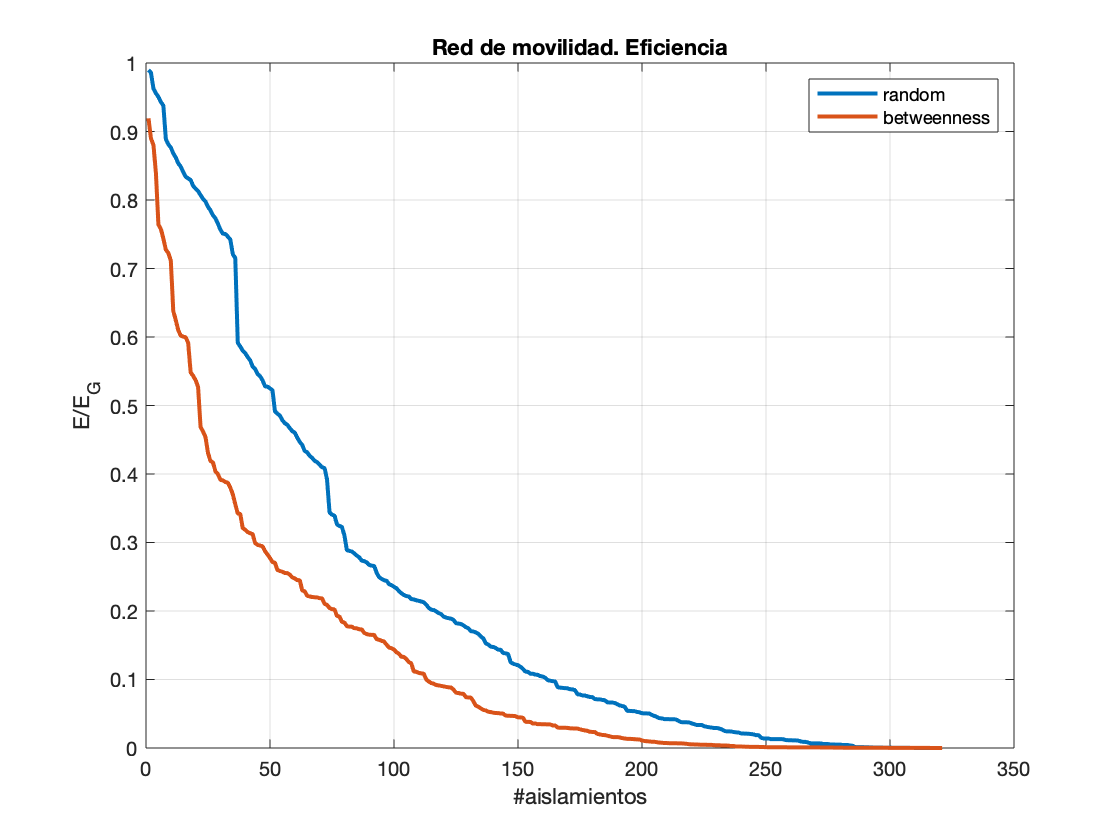

hold on;
plot(effbtw, 'Linewidth', 2);
hold off
legend('random','betweenness','Location','northeast')

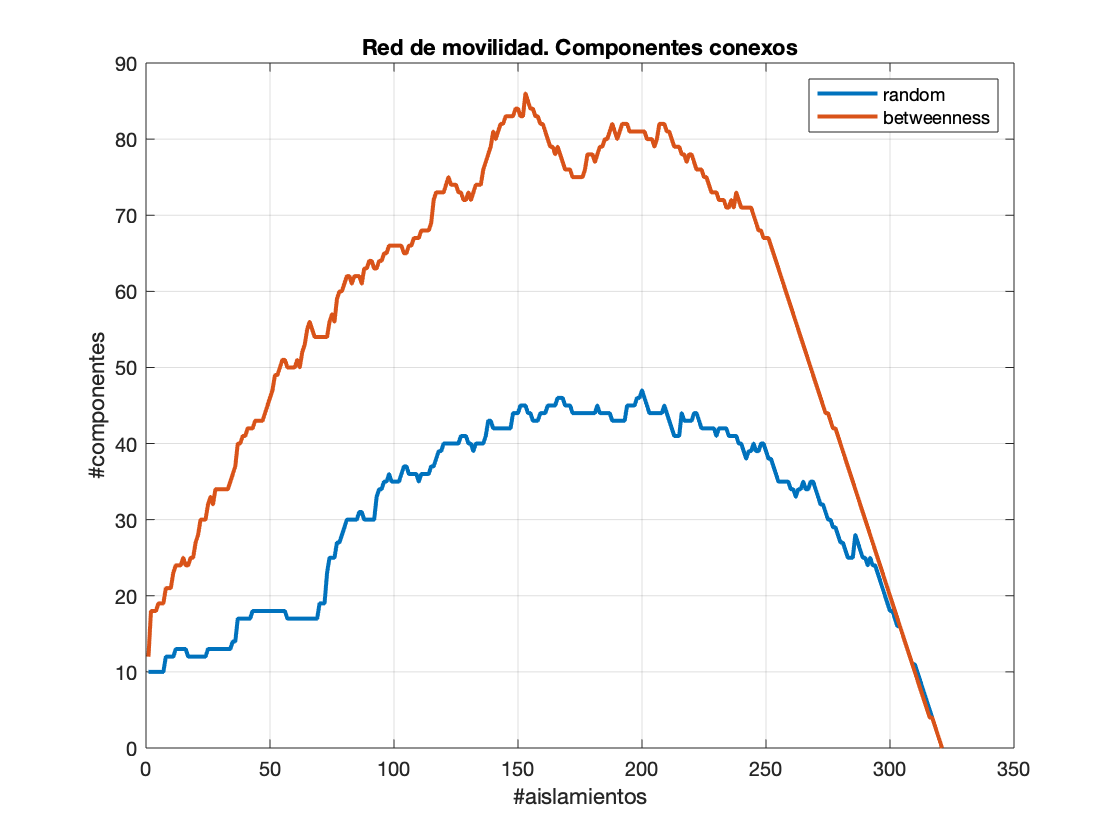

figure;
plot(connectedComponent, 'Linewidth', 2);
hold on;
plot(connectedComponentBtw, 'Linewidth', 2);
hold off
grid
title 'Red de movilidad. Componentes conexos'
xlabel('#aislamientos')
ylabel('#componentes')
legend('random','betweenness','Location','northeast')

slCharacterEncoding(encoding); 